# Minimum Airspeed for Takeoff vs Altitude

(Adapted from AE2440, AY24Q4, courtesy of Prof. Dobrokodov.)

Topics:

- Functions

- Logicals - using `find`

- `Interpolation`

- Vector element-wise arithmetic

- 2D line ploting

In this task, you need to explore and code in MATLAB the dependency of the minimum airspeed ($V_{min}
$) for takeoff of an aircraft on the runway altitude ($h_{runway}$). 

## Models:

Here is a mathematical model for the relationship:


$$V_{\text{min}} = \sqrt{\frac{ 2 M g}{\rho(h_{runway}) \, S  \,C_L}}$$


where the air density ($\rho$) is modeled with the exponential

$\rho(h) = \rho_0 e^{-\frac{h}{H}}$.

Consider the nominal falues for an F/A-18 Super Hornet.

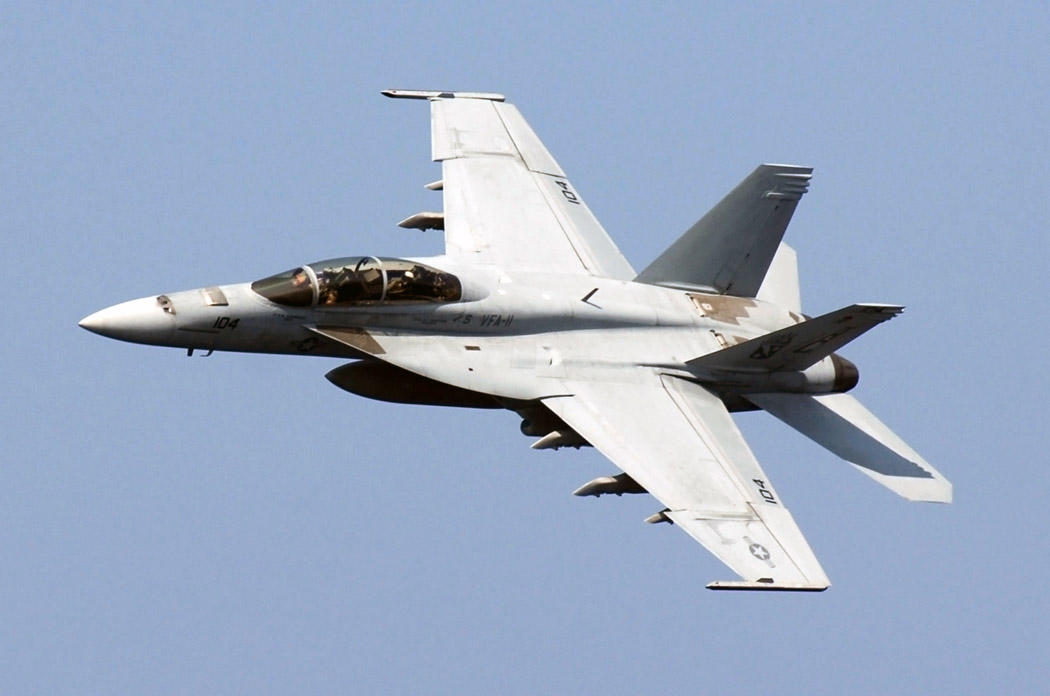

The constant coefficients are as follows:

- Lift coefficient - $C_L = 1.75$ dimensionless

- Wing surface area - $S = 37.2 \ m^2$ (per wing)

- Idealized altitude scale - $H = 8500 \ m$

- 
$$\rho_0=1.225\frac{kg}{m^3}$$


- Acceleration of gravity - $g = 9.81 \ m/s^2$

Consider two configurations for the aircraft mass

- Empty - $M = 14500 \ kg$

- Max Takeoff Weight - $M = 30000 \ kg
$

Exercises:

- Write a two local functions to calculate the relationship based on the prototypes below.

- Create a *well-documented* plot of the $V_{min}(h_{runway})$ for the two configurations (Empty and Max Takeoff Weight) as altitude varies 0 and 5000 m with step size of 100 m.  Use different line types, colors and line widths for the two line plots.  Inlcude a legend in a place that it doesn't obscure the information.  Include labels (with units) on the axes.

- From #2 you should have vectors for $h_{runway}$ and $V_{min}$ of equal length.  Use the `find` function to locate the following elements in the vectors:  For an empty aircraft with a maximum speed of 70 m/s, what is the maximum runway altitude for which it can take off?  For an aircraft at max. weight that is limited to 90 m/s, what is the maximum runway altitude?  Programmatically annotate your original figure with these two points with markers. 

- Repeat #3 using the `interp1` function.  Add a second marker on each line to visualize the interpolated points on the altitude vs. velocity axes. 

## Local functions

Takeoff speed as a function fo altitude and aircraft mass.

function vmin = takeoff_speed(h, m)
    % Minimum take off speed as a function of airstrip altitude and aircraft mass.
    % Input Arguments:
    % - h: Runway altitude (m) [numeric, scalar or vector]
    % - m: Aircraft mass (kg) [numeric, scalar]
    % Return Variables: 
    % - vmin: Minimum takeoff speed (m/s). 
    %           Same size as `h` [numeric, scalar or vector]

end

Local function called as a sub-routine of the `takeoff_speed` function

function rho = density(h)
    % Air density as a function of altitude
    % Input Arguments:
    % - h: Runway altitude (m) [numeric, scalar or vector]
    % Output Variables:
    % - rho: Air density values corresponding to the values in `h`.
    %           [numeric, scalar or vector

end




## Test the functions

Following an incremental development strategy, let's try this out before moving ahead.  Recall that 1 m/s ~ 2 kts.  Does it work for scalar input?

takeoff_speed(0, 14500)

How about for vector input?  We expect that as altitude increases, density decreases, so would need more airspeed to takeoff.

takeoff_speed([0 5000], 30000)

## Plot using vectors.

% Code to plot the two configurations on the same axes

## Find values

Finding values in two equal sized arrays,  Find the indexes corresponding to the condition. 

## Interpolation